clc;
clear;
close all;

## Parameters

Fs = 1000;              % Sampling frequency (Hz)
T = 1/Fs;
t = -1:T:1;             % Time vector

A = 1;                  % Pulse amplitude
tau = 0.2;              % Pulse width (seconds)

## Rectangular Pulse

x = A*(abs(t) <= tau/2).*cos(100*2*pi*t)

x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


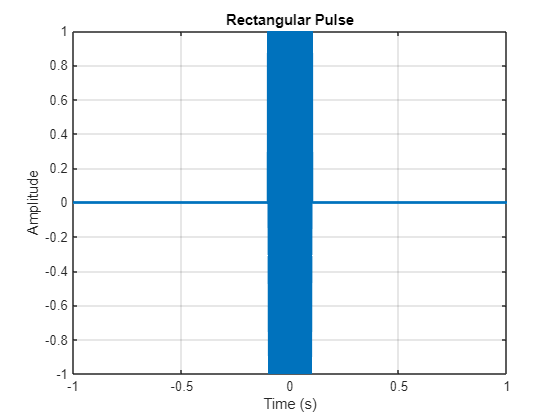


figure
plot(t,x,'LineWidth',2)
xlabel('Time (s)')
ylabel('Amplitude')
title('Rectangular Pulse')
grid on

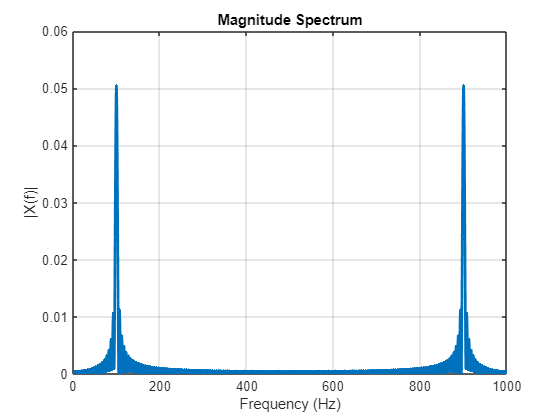

N = length(x);

Y = fft(x);

Magnitude = abs(Y)/N;
Phase = angle(Y);

f = (0:N-1)*(Fs/N);

figure

plot(f,Magnitude,'LineWidth',2)
xlabel('Frequency (Hz)')
ylabel('|X(f)|')
title('Magnitude Spectrum')
grid on
xlim([0 1000])

syms x

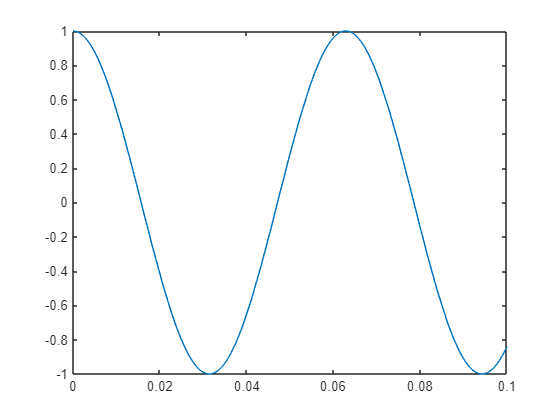


fplot(cos(100*x))
xlim([0,0.1])

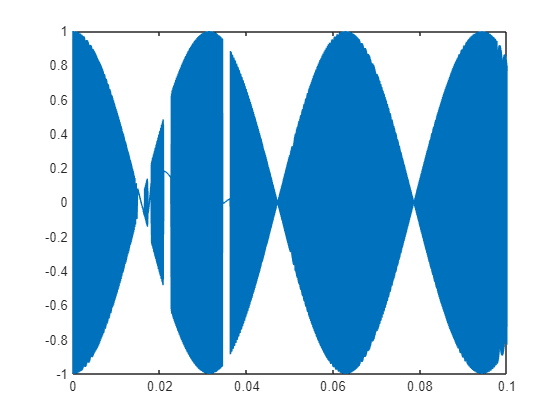

%modulating the signal
fplot(cos(100*x)*cos(1e5*x))
xlim([0,0.1])